# Project MSB1015: Ayahuasca

## Script 4: MANOVA test

## Guus Wilmink, i6156211

## Load data

clear all; close all;

% Load the data
load('.\processed_1_30Hz.mat');
load('.\processed_30_100Hz.mat');
elec = load(".\freqs_1-30Hz.mat").data_all_mean.elec;

% Specify bands
delta=2.5; theta=6; alpha=10.5; beta=21.5; slowgamma=40; fastgamma=75;

## Compute MANOVA test statistic using non-parametric cluster-based approach

Documentation: [https://www.fieldtriptoolbox.org/workshop/madrid2019/tutorial_stats/](https://www.fieldtriptoolbox.org/workshop/madrid2019/tutorial_stats/#preparing-the-dataset)

Related article:[doi.org/10.1016/j.jneumeth.2007.03.024](https://doi-org.mu.idm.oclc.org/10.1016/j.jneumeth.2007.03.024)

**Select settings for analysis in next chunks**

band          = 10.5;       % Frequency band
neighbourdist = 40; % Set neighbour distance threshold (channels are neighbours if distance < neighbourdist)

% Prepare data according to band selection
if ismember(band, [delta theta alpha beta])
    dat = processed_1_30Hz;
    if band == delta
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,1));
            dat{trial}.freq        = delta;
        end
    end
    if band == theta
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,2));
            dat{trial}.freq        = theta;
        end
    end
    if band == alpha
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,3));
            dat{trial}.freq        = alpha;
        end
    end
    if band == beta
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,4));
            dat{trial}.freq        = beta;
        end
    end
else
    dat = processed_30_100Hz;
     if band == slowgamma
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,1));
            dat{trial}.freq        = slowgamma;
        end
    end
    if band == fastgamma
        for trial = 1:6
            dat{trial}.powspctrm_b = squeeze(dat{trial}.powspctrm_b(:,:,2));
            dat{trial}.freq        = fastgamma;
        end
    end
end

**Prepare neighbouring channels**

% Prepare neighbours
cfg_neighb               = [];
cfg_neighb.elec          = elec;          % Specify electrode layout
cfg_neighb.method        ='distance';     % Method for identifying neighbours
cfg_neighb.neighbourdist = neighbourdist; % Maximum distance for channels to be neighbours
cfg_neighb.feedback      = 'yes'          % Plot neighbours 'yes'/'no'

cfg_neighb = struct with fields:
             elec: [1×1 struct]
           method: 'distance'
    neighbourdist: 40
         feedback: 'yes'


-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

using electrodes specified in the configuration
there are on average 4.0 neighbours per channel
using electrodes specified in the configuration
the call to "ft_neighbourplot" took 1 seconds


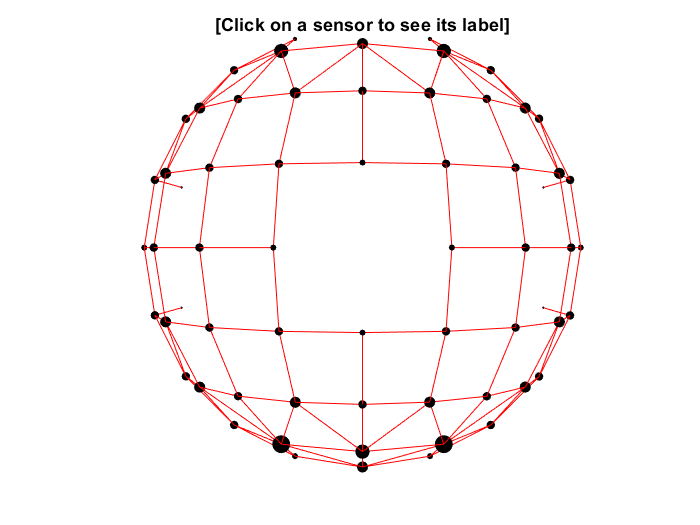

the call to "ft_prepare_neighbours" took 1 seconds


cfg_neighb.neighbours    = ft_prepare_neighbours(cfg_neighb); % Define neighbours

**Perform MANOVA test**

% Design matrix
nsubj                     = size(dat{1}.powspctrm_b,1); % Number of subjects (16)
design                    = [repmat(1:nsubj, 1, 6);...  % Design matrix row 1: unit of observations (subjects)
                             repelem(1:6, nsubj)];      % Design matrix row 2: independent variable (trials)

% Configuration
cfg                  = [];
cfg.neighbours       = cfg_neighb.neighbours;       % Set neighbours
cfg.elec             = elec;                        % Set electrode layout
cfg.parameter        = 'powspctrm_b';               % Set parameter for testing
cfg.frequency        = band;                        % Specify frequency band
cfg.channel          = 'all';                       % Channel selection
cfg.method           = 'ft_statistics_montecarlo';  % use the Monte Carlo method to calculate probabilities
cfg.statistic        = 'ft_statfun_depsamplesFmultivariate';    % use the dependent samples T-statistic as a measure to evaluate the effect at each sample
cfg.correctm         = 'cluster';                   % Use cluster-based approach for corrections
cfg.clusteralpha     = 0.05;                        % threshold for the sample-specific test, is used for thresholding
cfg.clusterstatistic = 'maxsum';                    % Use max sum of channel statistics across permutations for cluster
cfg.clusterthreshold = 'nonparametric_common';      % Cluster threshold method
cfg.minnbchan        = 2;                           % minimum number of neighbouring channels that is required
cfg.tail             = 1;                           % test only the right tail with MANOVA (left tail does not make sense with this test)
cfg.clustertail      = cfg.tail;                    % test only the right tail with MANOVA (left tail does not make sense with this test)
cfg.alpha            = 0.05;                        % alpha level of the permutation test
cfg.computeprob      = 'yes';                       % Compute probabibilities 'yes'/'no'
cfg.numrandomization = 5000;                        % number of random permutations
cfg.design           = design;                      % set design matrix
cfg.uvar             = 1;                           % Unit variable (subjects; row 1 of design matrix)
cfg.ivar             = 2;                           % Independent variable (trials; row 2 of design matrix)

% MANOVA test
[stat] = ft_freqstatistics(cfg, dat{:});

the call to "ft_selectdata" took 0 seconds
using specified neighbours for the channels
there are on average 4.0 neighbours per channel
the call to "ft_prepare_neighbours" took 0 seconds
using "ft_statistics_montecarlo" for the statistical testing
using "ft_statfun_depsamplesFmultivariate" for the single-sample statistics
constructing randomized design
total number of measurements     = 96
total number of variables        = 2
number of independent variables  = 1
number of unit variables         = 1
number of within-cell variables  = 0
number of control variables      = 0
using a permutation resampling approach
repeated measurement in variable 1 over 16 levels
number of repeated measurements in each level is 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 
the maximum number of unique permutations is 2821109907456
generated 5000 random permutations
using a nonparametric threshold for clustering
computing statistic
estimated time per randomization is 0.03 seconds
computing statistic 5000 from 5000

found

using a cluster-based method for multiple comparison correction
the returned probabilities and the thresholded mask are corrected for multiple comparisons
the call to "ft_freqstatistics" took 7 seconds
